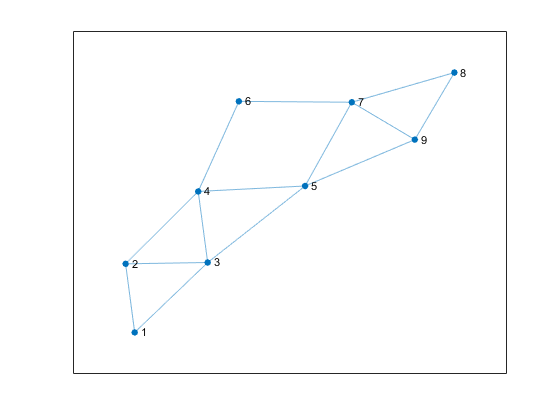

clc
clear all

global L S signS

%
R2 = [cos(pi/3) -sin(pi/3);
      sin(pi/3) cos(pi/3)];
R3 = [cos(pi) -sin(pi);
      sin(pi) cos(pi)];

S1 =  eye(2);
S2 = R2;
S3 = R3;

S = blkdiag(S1,S2,S1,S1,S2,S2,S1,S3,S3);

signS = blkdiag(eye(7),-eye(2)); 
sgnS = signS*ones(9,1);

[V,D] = eig(S*kron(signS,eye(2)));
n = 9;
m = 14;
d = 2;

s = [1 1 2 2 3 3 4 4 5 5 6 7 7 8];
t = [2 3 3 4 4 5 5 6 7 9 7 8 9 9];
G = graph(s,t);
H = incidence(G)'*eye(9);
figure
plot(G)

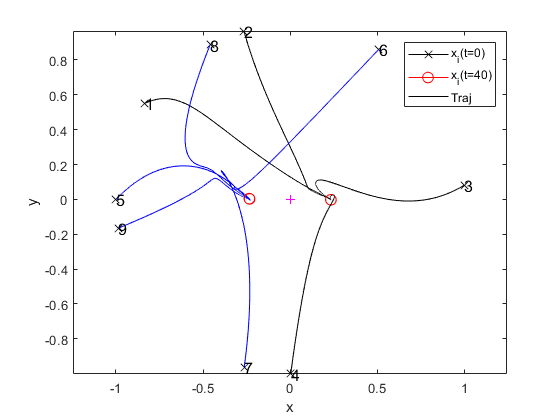

A12 = [1 sqrt(3)/2; 
       sqrt(3)/2 1];
A13 = [0 0; 0 1];
A23 = [2 1;
       1 1];
A24 = A13; 
A34 = A13;
A35 =-[1 0;
       0 0]; % negative edge
A45 = -diag([1, 2]); % negative edge
A78 = eye(2);
A79 = eye(2);
A89 = ones(2,2);
A46 = -A89; % negative edge
A67 = A12;
A57 = [1 0;0 0];
A59 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);
Z = zeros(2,2);

L = [A12+A13 -A12        -A13           Z                   Z        Z        Z            Z  Z;
     -A12    A12+A23+A24 -A23        -A24                   Z        Z        Z            Z  Z;
     -A13    -A23    A13+A23+A34-A35 -A34                -A35        Z        Z            Z  Z;
      Z      -A24        -A34        A24+A34-A45-A46     -A45     -A46        Z            Z  Z;
      Z      Z           -A35        -A45    -A35-A45+A57+A59        Z     -A57            Z  -A59;
      Z      Z           Z           -A46                   Z -A46+A67     -A67            Z  Z;
      Z      Z           Z           Z                   -A57     -A67  A57+A67+A78+A79 -A78  -A79;
      Z      Z           Z           Z                      Z        Z      -A78     A78+A89  -A89;
      Z      Z           Z           Z                   -A59        Z      -A79        -A89  A59+A79+A89];


% Initial condition
rng(7);
%x0 = 4*(rand(18,1)-0.5);
x0=[];
for i = 1:9
    r = 2*(rand(2,1)-0.5);
    x0 = [x0;r/norm(r)];        
end

[t,x] = ode45(@control_law,[0:0.01:40],x0);
t_end = length(t);
% Bieu dien tren do thi
str3 ='#C0C0C0';
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;

figure
hold on;
for i=1:9
    plot(x(1,2*i-1)',x(1,2*i)',"Marker","x","Color","k","MarkerSize",8);
    plot(x(t_end,2*i-1)',x(t_end,2*i)',"Marker","o","Color","r","MarkerSize",8);
    if i<5
        plot(x(:,2*i-1)',x(:,2*i)','-k');
    else
        plot(x(:,2*i-1)',x(:,2*i)','-b');
    end
    text((x(1,2*i-1))',(x(1,2*i))',num2str(i),"Color",'k',"FontSize",12);
end

plot(0,0,'Marker',"+","Color","m")

axis equal
% xlim([-6,6])
% ylim([-6,6])
box on
xlabel x
ylabel y
legend({'x_i(t=0)','x_i(t=40)','Traj'})
grid off

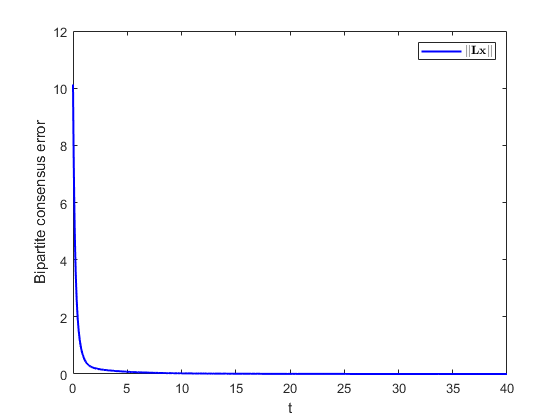


err = zeros(1,length(t));

for i = 1:length(t)
    err(1,i) = norm(L*x(i,:)');
end

figure
hold on
plot(t,err,'-b','LineWidth',1.5)
xlabel('t')
ylabel('Bipartite consensus error')
legend('$\|\mathbf{L}\mathbf{x}\|$',"interpreter","latex")
box on

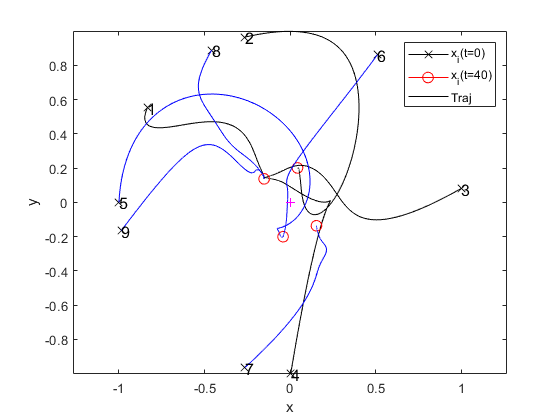

[t,x] = ode45(@control_law1,[0:0.01:40],x0);
t_end = length(t);
% Bieu dien tren do thi
str3 ='#C0C0C0';
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;

figure
hold on;
for i=1:9
    plot(x(1,2*i-1)',x(1,2*i)',"Marker","x","Color","k","MarkerSize",8);
    plot(x(t_end,2*i-1)',x(t_end,2*i)',"Marker","o","Color","r","MarkerSize",8);
    if i<5
    %plot(x(:,2*i-1)',x(:,2*i)','LineWidth',1,"Color",color3,"LineStyle","-");
        plot(x(:,2*i-1)',x(:,2*i)','-k');
    else
        plot(x(:,2*i-1)',x(:,2*i)','-b');
    end
    text((x(1,2*i-1))',(x(1,2*i))',num2str(i),"Color",'k',"FontSize",12);
end

plot(0,0,'Marker',"+","Color","m")

axis equal
box on
xlabel x
ylabel y
legend({'x_i(t=0)','x_i(t=40)','Traj'})
grid off

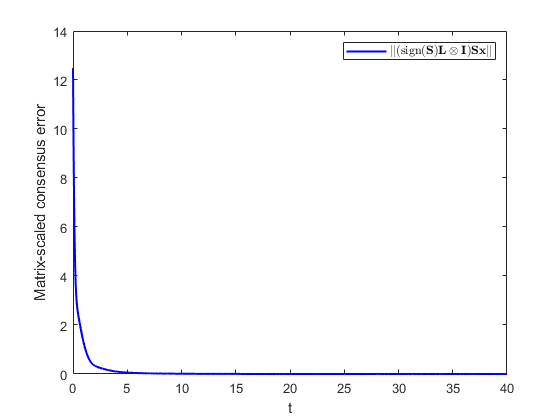

for i = 1:length(t)
    err(1,i) = norm(kron(signS,eye(2))*L*S*x(i,:)');
end

figure
hold on
plot(t,err,'-b','LineWidth',1.5)
xlabel('t')
ylabel('Matrix-scaled consensus error')
legend('$\|({\rm sign}(\mathbf{S})\mathbf{L}\otimes\mathbf{I})\mathbf{S}\mathbf{x}\|$',"interpreter","latex")
box on

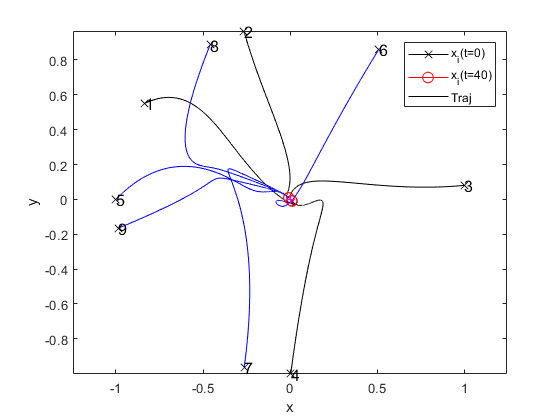


%% sign unbalanced structure: include a positive edge between (3,6) => convergence
L = [A12+A13 -A12        -A13           Z                   Z        Z        Z            Z  Z;
     -A12    A12+A23+A24 -A23        -A24                   Z        Z        Z            Z  Z;
     -A13    -A23    A13+A23+A34-A35+eye(2) -A34                -A35    -eye(2)      Z            Z  Z;
      Z      -A24        -A34        A24+A34-A45-A46     -A45     -A46        Z            Z  Z;
      Z      Z           -A35        -A45    -A35-A45+A57+A59        Z     -A57            Z  -A59;
      Z      Z           -eye(2)           -A46                   Z -A46+A67+eye(2)     -A67            Z  Z;
      Z      Z           Z           Z                   -A57     -A67  A57+A67+A78+A79 -A78  -A79;
      Z      Z           Z           Z                      Z        Z      -A78     A78+A89  -A89;
      Z      Z           Z           Z                   -A59        Z      -A79        -A89  A59+A79+A89];

[t,x] = ode45(@control_law,[0:0.01:40],x0);
t_end = length(t);
% Bieu dien tren do thi
str3 ='#C0C0C0';
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;

figure
hold on;
for i=1:9
    plot(x(1,2*i-1)',x(1,2*i)',"Marker","x","Color","k","MarkerSize",8);
    plot(x(t_end,2*i-1)',x(t_end,2*i)',"Marker","o","Color","r","MarkerSize",8);
    if i<5
    %plot(x(:,2*i-1)',x(:,2*i)','LineWidth',1,"Color",color3,"LineStyle","-");
        plot(x(:,2*i-1)',x(:,2*i)','-k');
    else
        plot(x(:,2*i-1)',x(:,2*i)','-b');
    end
    text((x(1,2*i-1))',(x(1,2*i))',num2str(i),"Color",'k',"FontSize",12);
end

plot(0,0,'Marker',"+","Color","m")

axis equal
box on
xlabel x
ylabel y
legend({'x_i(t=0)','x_i(t=40)','Traj'})
grid off

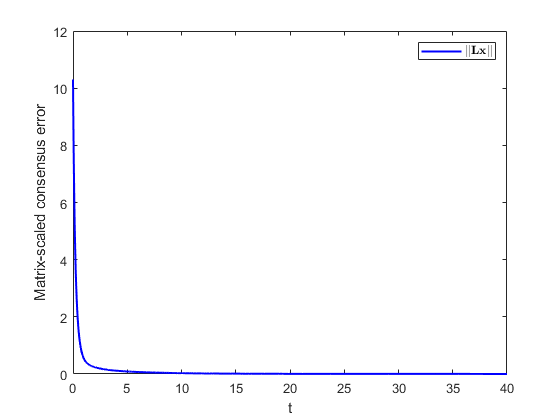


err = zeros(1,length(t));

% for i = 1:length(t)
%     err(1,i) = norm(kron(signS,eye(2))*L*S*x(i,:)');
% end
for i = 1:length(t)
    err(1,i) = norm(L*x(i,:)');
end

figure
hold on
plot(t,err,'-b','LineWidth',1.5)
xlabel('t')
ylabel('Matrix-scaled consensus error')
legend('$\|\mathbf{L}\mathbf{x}\|$',"interpreter","latex")
box on

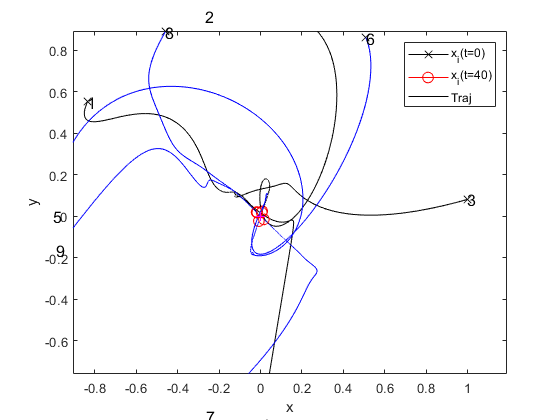



% with scaling matrices
[t,x] = ode45(@control_law1,[0:0.01:40],x0);
t_end = length(t);
% Bieu dien tren do thi
str3 ='#C0C0C0';
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;

figure
hold on;
for i=1:9
    plot(x(1,2*i-1)',x(1,2*i)',"Marker","x","Color","k","MarkerSize",8);
    plot(x(t_end,2*i-1)',x(t_end,2*i)',"Marker","o","Color","r","MarkerSize",8);
    if i<5
    %plot(x(:,2*i-1)',x(:,2*i)','LineWidth',1,"Color",color3,"LineStyle","-");
        plot(x(:,2*i-1)',x(:,2*i)','-k');
    else
        plot(x(:,2*i-1)',x(:,2*i)','-b');
    end
    text((x(1,2*i-1))',(x(1,2*i))',num2str(i),"Color",'k',"FontSize",12);
end

plot(0,0,'Marker',"+","Color","m")

axis equal
box on
xlabel x
ylabel y
legend({'x_i(t=0)','x_i(t=40)','Traj'})
grid off

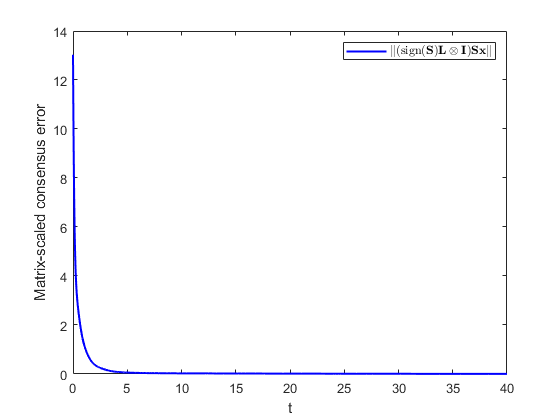


for i = 1:length(t)
    err(1,i) = norm(kron(signS,eye(2))*L*S*x(i,:)');
end

figure
hold on
plot(t,err,'-b','LineWidth',1.5)
xlabel('t')
ylabel('Matrix-scaled consensus error')
legend('$\|({\rm sign}(\mathbf{S})\mathbf{L}\otimes\mathbf{I})\mathbf{S}\mathbf{x}\|$',"interpreter","latex")
box on

function dpdt = control_law(t,p)
    global L
    dpdt = -L*p;
end

function dpdt = control_law1(t,p)
    global L S signS
    dpdt = -kron(signS,eye(2))*L*S*p;
    %dpdt = -L*p;
end